## Creating Cambers for MATLAB

This script will guide you through the necessary airfoils to run the foil study. This is a parallel script for generating cambers in MATLAB to be used in place of the R script `Creating_cambers.Rmd`. It serves the same purpose, generating camber files to use with XFOIL in MATLAB for those who prefer using MATLAB only. 

This script will generate all airfoils needed to run the foil study from the list provided in `./data/camber_list.csv`. This is accomplished by altering the original airfoil `./data/AS6091.csv`. The output will be located in `./data`. 

Adding necessary scripts to MATLAB path: 

addpath('../src/matlab')

### Process of adjusting cambers

These functions work by loading in the base airfoil, AS 6091, and adjusting it to a new camber. 

Loading 2D template airfoil: 

foil = readtable("../data/airfoils/AS6091.dat");
X = foil{:, 1};
Y = foil{:, 2};

Plot foil:  

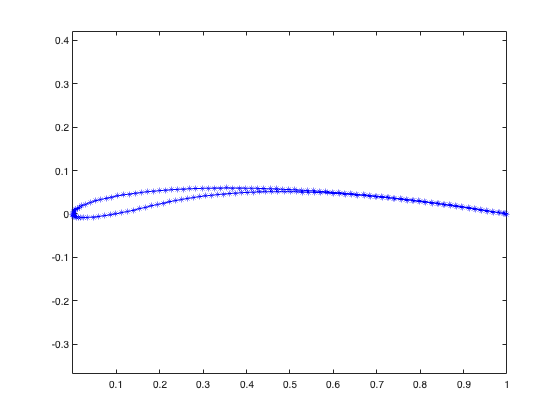

plot(X, Y, 'b*-')
axis equal

Define a new camber: 

camber_new = 0.05;

Calculate the midline: 

foil_midline_sm = find_midline(X,Y,0);
midline_x = foil_midline_sm{:, 'x'};
midline_y = foil_midline_sm{:, 'y'};

Plot foil with midline: 

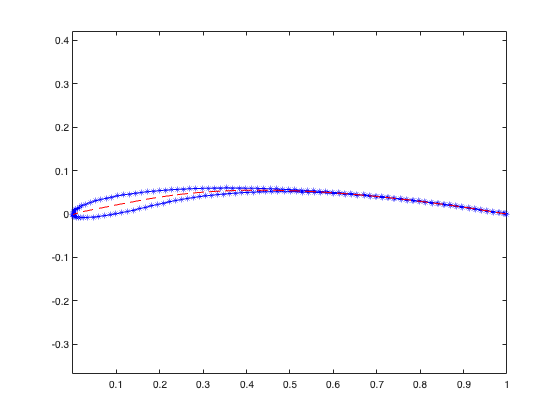

plot(X, Y, 'b*-')
hold on
axis equal
plot(midline_x, midline_y, 'r--')
hold off

Check camber: 

calc_camber(midline_x, midline_y)

ans = 0.0560

Create a new midline: 

new_midline = adjust_midline(foil_midline_sm, camber_new);

Plot new midline:

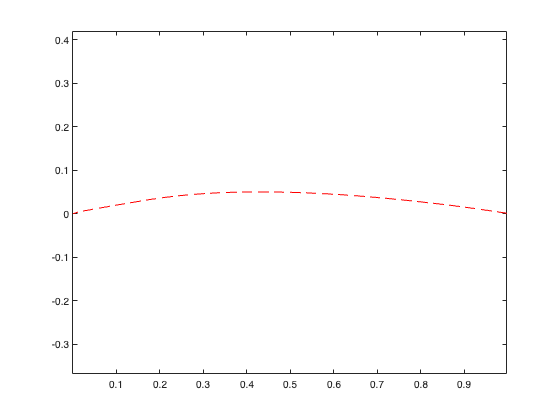

plot(new_midline{:,'x'}, new_midline{:,'y'}, 'r--')
axis equal

Create a new foil based on the new midline and thicknesses: 

new_foil = create_new_foil(new_midline);

Plot new foil: 

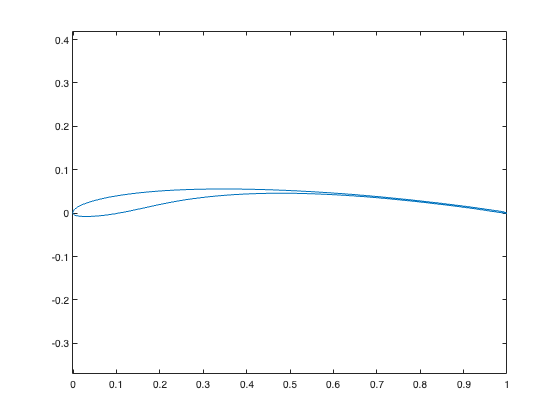

plot(new_foil{:, 'x'}, new_foil{:, 'y'})
axis equal

Check camber of new foil: 

new_foil_midline = find_midline(new_foil{:, 'x'}, new_foil{:, 'y'},0);
calc_camber(new_foil_midline{:, 'x'}, new_foil_midline{:,'y'})

### Produce airfoils required for foil study

Run the following to produce the airfoils necessary for running the XFOIL study below. 

Load airfoil: 

foil = readtable("../data/airfoils/AS6091.dat");
foil.Properties.VariableNames = {'x', 'y'};

#### Grid parameter set

mkdir('../data/airfoils/')

mkdir('../data/airfoils/grid_camber_files')
mkdir('../results/grid_noLogRe_matfiles')

Load parameters and extract cambers:

grid_params = readtable("../data/parameters/grid_Params_noLogRe.csv");
grid_params.Properties.VariableNames = {'Re', 'aoa', 'camber'};
camber_list = unique(grid_params{:,'camber'});

Produce and save each camber file:

for i = 1:length(camber_list)
    camber_new = camber_list(i);
    foil_midline_sm = find_midline(foil{:,'x'}, foil{:,'y'}, 0);
    new_midline = adjust_midline(foil_midline_sm, camber_new);
    new_foil = create_new_foil(new_midline);
    writetable(new_foil, append("../data/airfoils/grid_camber_files/AS_camber_",...
        num2str(camber_new), ".dat"), ...
        'WriteVariableNames', false)
end

#### gPC parameter set

mkdir('../data/airfoils/')

mkdir('../data/airfoils/gPC_camber_files')
mkdir('../results/gPC_noLogRe_matfiles')

mkdir('../results/gPC_LogRe_matfiles')

Load parameters and extract cambers:

gpc_params = readtable("../data/parameters/gPC_Params_noLogRe.csv");
gpc_params.Properties.VariableNames = {'Re', 'aoa', 'camber'};
camber_list = unique(gpc_params{:,'camber'});

Produce and save each camber file:

for i = 1:length(camber_list)
    camber_new = camber_list(i);
    foil_midline_sm = find_midline(foil{:,'x'}, foil{:,'y'}, 0);
    new_midline = adjust_midline(foil_midline_sm, camber_new);
    new_foil = create_new_foil(new_midline);
    writetable(new_foil, append("../data/airfoils/gPC_camber_files/AS_camber_",...
        num2str(camber_new), ".dat"), ...
        'WriteVariableNames', false)
end

#### NN parameter set

mkdir('../data/airfoils/')

mkdir('../data/airfoils/NN_camber_files')
mkdir('../results/NN_noLogRe_matfiles')

mkdir('../results/NN_LogRe_matfiles')

Load parameters and extract cambers:

nn_params = readtable("../data/parameters/NN_Params_noLogRe.csv");
nn_params.Properties.VariableNames = {'Re', 'aoa', 'camber'};
camber_list = unique(nn_params{:,'camber'});

Produce and save each camber file:

for i = 1:length(camber_list)
    camber_new = camber_list(i);
    foil_midline_sm = find_midline(foil{:,'x'}, foil{:,'y'}, 0);
    new_midline = adjust_midline(foil_midline_sm, camber_new);
    new_foil = create_new_foil(new_midline);
    writetable(new_foil, append("../data/airfoils/NN_camber_files/AS_camber_",...
        num2str(camber_new), ".dat"), ...
        'WriteVariableNames', false)
end

## Next steps... 

Now that all the airfoils have been created, you can move on to running simulations in Matlab XFOIL! 